Exercises on multiobjective optimization problems

**a) Is it a convex problem? Is it a linear problem?**

**b) Do Pareto minima exist? Why?**

**c) Does the Abadie constraint qualification hold in any feasible point?**

**d) Find a subset of Pareto minima by using the scalarization method. Are there other**

**Pareto minima?**

**e) Find a subset of Pareto weak minima by using the scalarization method. Are there**

**other Pareto weak minima?**

**f) Find all the solutions of the KKT system. Are they Pareto weak minima? Are they**

**Pareto minima?**

**g) Plot the set f (Ω) (image of the feasible region). Find all the efficient points and**

**weakly efficient points of f (Ω). Find all the Pareto minima and Pareto weak minima.**

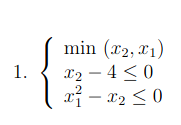

f1 = @(x1,x2) x2;
f2 = @(x1,x2) x1;

c1 = @(x1,x2) x2 - 4;
c2 = @(x1,x2) x1.^2 - x2;

Q = [4 0
     0 4];

fprintf("Eig-Value:");

Eig-Value:

disp(eig(Q));

     4
     4



x1 = linspace(-10, 10, 100);
x2 = linspace(-10, 10, 100);


[X1,X2] = meshgrid(x1,x2);

F1 = f1(X1,X2); 
F2 = f2(X1,X2);
C1 = c1(X1,X2);
C2 = c2(X1,X2);

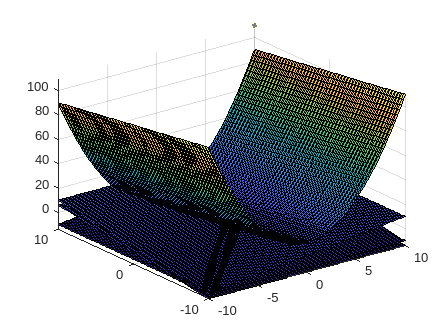

% 3D 
figure;
surf(X1,X2,F1);
hold on
surf(X1,X2,F2);
surf(X1,X2,C1);
surf(X1,X2,C2);

xlabel = ('x1');
ylabel = ('x1');
zlabel = ('Objective Function');


hold off

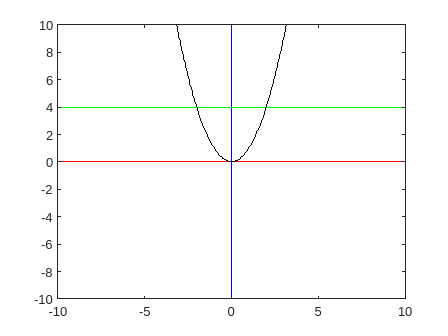

% 2D
figure;
contour(X1,X2,F1, [0 0], 'EdgeColor','r');
hold on
contour(X1,X2,F2, [0 0], 'EdgeColor','b');
contour(X1,X2,C1, [0 0], 'EdgeColor','g');
contour(X1,X2,C2, [0 0], 'EdgeColor','k');

hold off

% Scalarization method 
f_1 = x2;
f_2 = x1;

alpha = 0.001:0.001:0.999;

for alpha = alpha
    f = [alpha
         1-alpha];
end



Operator '*' is not supported for operands of type 'function_handle'.